## Linear Parametrization Elastic Transmission

In this case we have both kinetic energy one for the motor and the second for the links

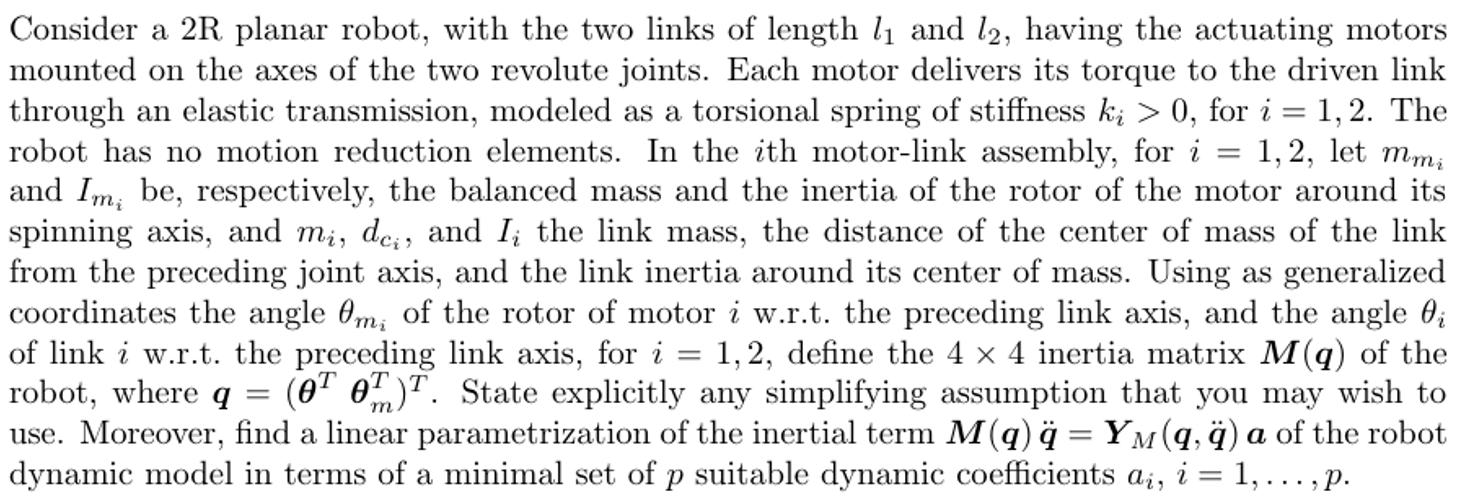

syms theta1 theta2 dtheta1 dtheta2 l1_m1 l2_m2 l1 l2 d1 d2 I1 I2 g0 m1 m2 m2_m2 positive
syms I1_m1 I2_m2 m1_m2 dtheta_m1 dtheta_m2 positive
syms a1 a2 a3 a4 a5 a6 ddq1 ddq2 ddq3 ddq4 real

% Kinetic Energy of the motors (rotational)
T_m1 = 0.5*(I1_m1)*dtheta_m1^2;
T_m2 = 0.5*m2_m2*l1^2*dtheta1^2 + 0.5*I2_m2*(dtheta1 + dtheta_m2)^2;

% Kinetic energy of the links
T_l1 = 0.5*(I1 + m1*d1^2)*dtheta1^2;

% Define the positions of link 2 (end-effector)
x2 = l1*cos(theta1) + d2*cos(theta1 + theta2);
y2 = l1*sin(theta1) + d2*sin(theta1 + theta2);

% Velocities of the end-effector (link 2)
vx2 = diff(x2, theta1)*dtheta1 + diff(x2, theta2)*dtheta2;
vy2 = diff(y2, theta1)*dtheta1 + diff(y2, theta2)*dtheta2;

% Rotational and translational kinetic energy of link 2
T_rot_l2 = 0.5*I2*(dtheta1 + dtheta2)^2;
T_tr_l2 = 0.5*m2*[vx2 vy2]*[vx2; vy2];
T_l2 = T_rot_l2 + T_tr_l2;

% Total kinetic energy
T = simplify(T_m1 + T_m2 + T_l1 + T_l2, 'steps', 1000);

% Now compute the elements of the 4x4 inertia matrix M(q) by differentiating T
M11 = diff(T, dtheta1, 2);  % Second derivative with respect to dtheta1
M12 = diff(T, dtheta1, dtheta2);  % Mixed partial derivative
M13 = diff(T, dtheta1, dtheta_m1);  % Mixed derivative for motor
M14 = diff(T, dtheta1, dtheta_m2);  % Mixed derivative for motor

M21 = M12;  % Symmetry of inertia matrix
M22 = diff(T, dtheta2, 2);  % Second derivative with respect to dtheta2
M23 = diff(T, dtheta2, dtheta_m1);  % Mixed derivative for motor
M24 = diff(T, dtheta2, dtheta_m2);  % Mixed derivative for motor

M31 = M13;  % Symmetric
M32 = M23;  % Symmetric
M33 = diff(T, dtheta_m1, 2);  % Second derivative with respect to dtheta_m1
M34 = diff(T, dtheta_m1, dtheta_m2);  % Mixed derivative for motors

M41 = M14;  % Symmetric
M42 = M24;  % Symmetric
M43 = M34;  % Symmetric
M44 = diff(T, dtheta_m2, 2);  % Second derivative with respect to dtheta_m2

% Assemble the 4x4 inertia matrix M(q)
M_q = [M11, M12, M13, M14;
       M21, M22, M23, M24;
       M31, M32, M33, M34;
       M41, M42, M43, M44];

% Display the 4x4 inertia matrix
disp('Inertia Matrix M(q):');

Inertia Matrix M(q):


disp(M_q);

$$\begin{array}{l} \left(\begin{array}{cccc} I_{1}+I_{2}+I_{2,\mathrm{m2}}+{d_{1}}^{2}\,m_{1}+{d_{2}}^{2}\,m_{2}+{l_{1}}^{2}\,m_{2}+{l_{1}}^{2}\,m_{2,\mathrm{m2}}+2\,d_{2}\,l_{1}\,m_{2}\,\cos\left(\theta_{2}\right) & \sigma_{1} & 0 & I_{2,\mathrm{m2}}\\ \sigma_{1} & m_{2}\,{d_{2}}^{2}+I_{2} & 0 & 0\\ 0 & 0 & I_{1,\mathrm{m1}} & 0\\ I_{2,\mathrm{m2}} & 0 & 0 & I_{2,\mathrm{m2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=m_{2}\,{d_{2}}^{2}+l_{1}\,m_{2}\,\cos\left(\theta_{2}\right)\,d_{2}+I_{2} \end{array}$$

### Parametrization Regressor matrix

ddq = [ddq1; ddq2; ddq3; ddq4;];
M_para = [a1+2*a2*cos(theta2)         a3+a4*cos(theta2)        0        a5;
           a3+a4*cos(theta2)                a3                 0        0;
                 0                          0                 a6        0;
                a5                          0                  0       a5;];

Ya = M_para*ddq

$$Ya = \left(\begin{array}{c} {\mathrm{ddq}}_{1}\,\left(a_{1}+2\,a_{2}\,\cos\left(\theta_{2}\right)\right)+{\mathrm{ddq}}_{2}\,\left(a_{3}+a_{4}\,\cos\left(\theta_{2}\right)\right)+a_{5}\,{\mathrm{ddq}}_{4}\\ {\mathrm{ddq}}_{1}\,\left(a_{3}+a_{4}\,\cos\left(\theta_{2}\right)\right)+a_{3}\,{\mathrm{ddq}}_{2}\\ a_{6}\,{\mathrm{ddq}}_{3}\\ a_{5}\,{\mathrm{ddq}}_{1}+a_{5}\,{\mathrm{ddq}}_{4} \end{array}\right)$$


% Dynamic symbols
dynamic_symbols = [a1, a2, a3, a4, a5, a6];

Y = extract_Y_v3(Ya, dynamic_symbols);

disp('Regressor Matrix Y:');

Regressor Matrix Y:


disp(Y);

$$\left(\begin{array}{cccccc} {\mathrm{ddq}}_{1} & 2\,{\mathrm{ddq}}_{1}\,\cos\left(\theta_{2}\right) & {\mathrm{ddq}}_{2} & {\mathrm{ddq}}_{2}\,\cos\left(\theta_{2}\right) & {\mathrm{ddq}}_{4} & 0\\ 0 & 0 & {\mathrm{ddq}}_{1}+{\mathrm{ddq}}_{2} & {\mathrm{ddq}}_{1}\,\cos\left(\theta_{2}\right) & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & {\mathrm{ddq}}_{3}\\ 0 & 0 & 0 & 0 & {\mathrm{ddq}}_{1}+{\mathrm{ddq}}_{4} & 0 \end{array}\right)$$

function Y = extract_Y_v3(Ya, dynamic_symbols)
    % Estrae la matrice di regressione Y da un'espressione Ya lineare
    % nei simboli elencati in dynamic_symbols.
    %
    % Ya              : espressione simbolica (ad es. M*ddq + c + G)
    % dynamic_symbols : array contenente [a1, a2, ..., aN]
    %
    % Output: Y       : matrice che, moltiplicata per [a1; a2; ...; aN],
    %                   restituisce l'originale Ya.

    % Inizializzazione
    Y = sym([]);
    Y_columns = length(dynamic_symbols);
    % Assicuriamoci di avere dynamic_symbols come array riga
    dynamic_symbols = reshape(dynamic_symbols, 1, Y_columns);

    for i = 1:Y_columns
        % Costruisco un array di sostituzione: tutti zeri tranne un 1
        subs_array = zeros(1, Y_columns);
        subs_array(i) = 1;

        % Sostituisco in Ya: a_i=1, gli altri=0
        Yi = subs(Ya, dynamic_symbols, subs_array);

        % Concateno in colonna
        Y = [Y, Yi];
    end
end